# Segmenting with Lab Color Space

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

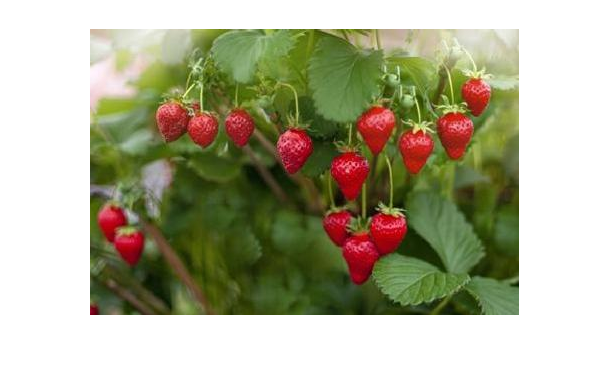

sbRGB = imread("./images/strawberryPlant.jpg");
imshow(sbRGB)

## Task 1

The `rgb2lab` function converts an image from RGB to Lab.

sbLab = rgb2lab(sbRGB);

## Task 2

A representation in the Lab color space has three channels:

- Luminance is stored in the first plane and contains brightness from black to white.

- The a* channel is stored in the second plane and contains a measurement of hue from green to red.

- The b* channel is stored in the third plane and contains a measurement of hue from blue to yellow.

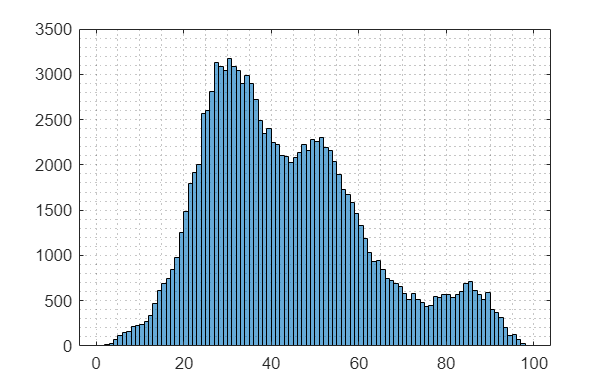

L = sbLab(:, :, 1);
histogram(L)
grid minor

## Task 3

To display the luminance plane, you need to scale the values to between 0 and 1. You can do this directly in the `imshow` command using square brackets.

`imshow``(``im``,``[])`

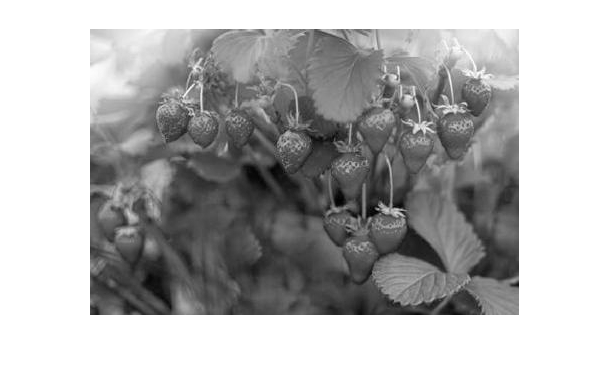

imshow(L, [])

## Task 4

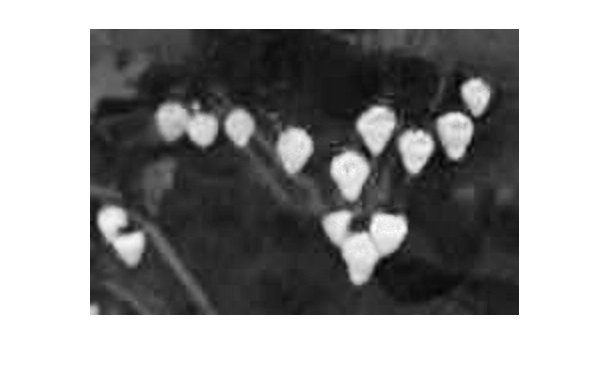

a = sbLab(:, :, 2);
imshow(a, [])

## Task 5

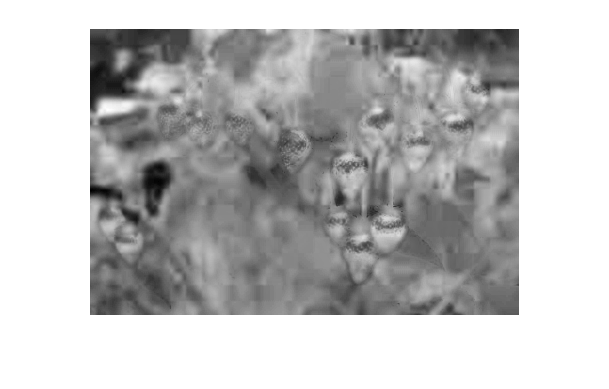

b = sbLab(:, :, 3);
imshow(b, [])

## Task 6

The a* plane does the best job of separating the red strawberries from the green background. You can view the intensity histogram to determine a threshold.

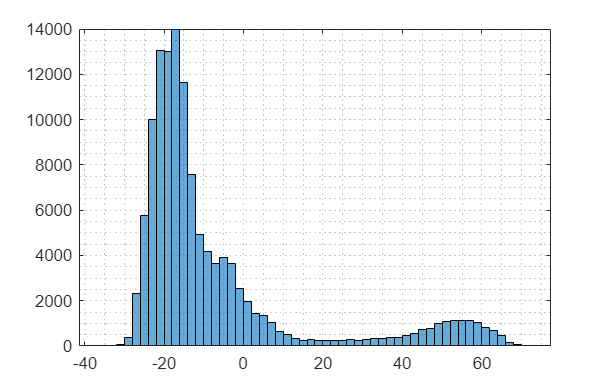

histogram(a)
grid minor

## Task 7

You can see two clusters of intensities in the a* channel. The higher values correspond to the strawberries, which have more red than green in them.

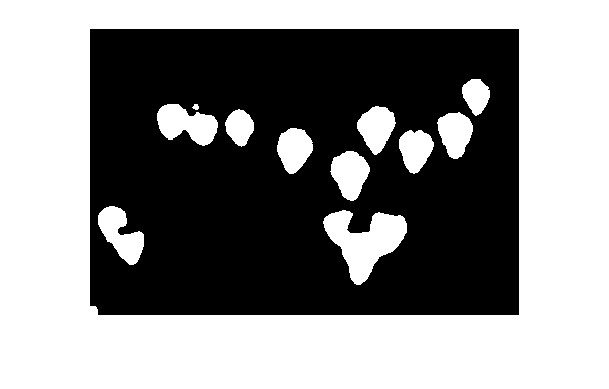

redSBmask = a > 21;
imshow(redSBmask)